## Задание диапазонов входных параметров

%% Задание диапазонов входов модели
% Угол подъема, град
theta_min = -5;   theta_max = 15;   theta_n = 5;

% Начальная скорость, м/с
v0_min     = 1;   v0_max     = 5;   v0_n     = 5;

% Открытие дроссельной заслонки, %
throttle_min = 10;   throttle_max = 20;   throttle_n = 5;

% Разбиваем диапазоны на сетку
theta  = linspace(theta_min,  theta_max,  theta_n);
v0     = linspace(v0_min,      v0_max,     v0_n);
throttle    = linspace(throttle_min,throttle_max,throttle_n);

% Создаём полный план эксперимента (все комбинации)
[Theta, V0, Thr] = ndgrid(theta, v0, throttle);
X = [Theta(:), V0(:), Thr(:)];  % входной набор данных Nx3

%% ОСНОВНЫЕ ПАРАМЕТРЫ МОДЕЛИ Vehicle_4WD
massVehicle      = 1500;        % кг
inertiaDriveShaft = 1.1;        % кг*м²
engineRPM0       = 1000;        % об/мин
ratioDiff        = 3.5;         % передаточное число дифференциала
radiusWheel      = 0.32;        % м
tireStiffness    = 200000;      % Н/м  
tireDamping      = 5000;        % Нс/м
inertiaLateral   = 0.01;        % кг*м² боковая инерция шины

## Серия экспериментов в Simulink

%% ПЛАН ЭКСПЕРИМЕНТА Vehicle_4WD
clear y_results;  % Результаты: [средняя_скорость_10с, конечная_скорость]


%% ПЛАН ЭКСПЕРИМЕНТА (замени на свой X!)
N = size(X, 1);
simTime = 5;
y_results = zeros(N, 2);  % [v_ср_10с, v_конец]

%% ОСНОВНОЙ ЦИКЛ
for i = 1:N
    fprintf('Эксперимент %d/%d: theta=%.3f, throttle=%.2f, v0=%.1f\n', ...
        i, N, X(i,1), X(i,2), X(i,3));
    
    % УСТАНОВКА ПАРАМЕТРОВ
    %set_param('Vehicle_4WD/v0', 'Value', num2str(X(i,3)));           % v0
    set_param('Vehicle_4WD/Vehicle Body', 'v', num2str(X(i,3)));     % дублируем
    
    % theta и throttle - найди блоки (замени пути!)
    set_param('Vehicle_4WD/Theta', 'Value', num2str(X(i,1)));     % theta?
    set_param('Vehicle_4WD/Thr', 'Value', num2str(X(i,2)));    % throttle?
    
    % Симуляция 10 секунд
    out = sim('Vehicle_4WD', 'StopTime', num2str(simTime));
    
    % ✅ СКОРОСТЬ ИЗ WORKSPACE (выполни whos после 1 симуляции!)
    clear time
    v_series = out.simlog_Vehicle_4WD.Vehicle_Body.v.series;
    t = time(v_series);
    v = values(v_series);
    y(i) = mean(v(t <= simTime));
    
    % Средняя за 10с и конечная
    v_mean_10s = mean(v);
    v_end = v(end);
    
    y_results(i,:) = [v_mean_10s, v_end];
    
    fprintf('  → v_ср(10с)=%.2f, v_конец=%.2f ✓\n', v_mean_10s, v_end);
end

Эксперимент 1/

  → v_ср(10с)=10.80, v_конец=25.59 ✓


Эксперимент 2/125

  → v_ср(10с)=10.52, v_конец=23.50 ✓


Эксперимент 3/125

  → v_ср(10с)=9.78, v_конец=21.28 ✓


Эксперимент 4/125

  → v_ср(10с)=9.57, v_конец=18.96 ✓


Эксперимент 5/125

  → v_ср(10с)=9.35, v_конец=16.58 ✓


Эксперимент 6/125

  → v_ср(10с)=10.80, v_конец=25.59 ✓


Эксперимент 7/125

  → v_ср(10с)=10.52, v_конец=23.50 ✓


Эксперимент 8/125

  → v_ср(10с)=9.78, v_конец=21.28 ✓


Эксперимент 9/125

  → v_ср(10с)=9.57, v_конец=18.96 ✓


Эксперимент 10/125

  → v_ср(10с)=9.35, v_конец=16.58 ✓


Эксперимент 11/125

  → v_ср(10с)=10.80, v_конец=25.59 ✓


Эксперимент 12/125

  → v_ср(10с)=10.52, v_конец=23.50 ✓


Эксперимент 13/125

  → v_ср(10с)=9.78, v_конец=21.28 ✓


Эксперимент 14/125

  → v_ср(10с)=9.57, v_конец=18.96 ✓


Эксперимент 15/125

  → v_ср(10с)=9.35, v_конец=16.58 ✓


Эксперимент 16/125

  → v_ср(10с)=10.80, v_конец=25.59 ✓


Эксперимент 17/125

  → v_ср(10с)=10.52, v_конец=23.50 ✓


Эксперимент 18/125

  → v_ср(10с)=9.78, v_конец=21.28 ✓


Эксперимент 19/125

  → v_ср(10с)=9.57, v_конец=18.96 ✓


Эксперимент 20/125

  → v_ср(10с)=9.35, v_конец=16.58 ✓


Эксперимент 21/125

  → v_ср(10с)=10.80, v_конец=25.59 ✓


Эксперимент 22/125

  → v_ср(10с)=10.52, v_конец=23.50 ✓


Эксперимент 23/125

  → v_ср(10с)=9.78, v_конец=21.28 ✓


Эксперимент 24/125

  → v_ср(10с)=9.57, v_конец=18.96 ✓


Эксперимент 25/125

  → v_ср(10с)=9.35, v_конец=16.58 ✓


Эксперимент 26/125

  → v_ср(10с)=12.43, v_конец=26.54 ✓


Эксперимент 27/125

  → v_ср(10с)=12.15, v_конец=24.53 ✓


Эксперимент 28/125

  → v_ср(10с)=11.76, v_конец=22.40 ✓


Эксперимент 29/125

  → v_ср(10с)=11.11, v_конец=20.16 ✓


Эксперимент 30/125

  → v_ср(10с)=10.88, v_конец=17.85 ✓


Эксперимент 31/125

  → v_ср(10с)=12.43, v_конец=26.54 ✓


Эксперимент 32/125

  → v_ср(10с)=12.15, v_конец=24.53 ✓


Эксперимент 33/125

  → v_ср(10с)=11.76, v_конец=22.40 ✓


Эксперимент 34/125

  → v_ср(10с)=11.11, v_конец=20.16 ✓


Эксперимент 35/125

  → v_ср(10с)=10.88, v_конец=17.85 ✓


Эксперимент 36/125

  → v_ср(10с)=12.43, v_конец=26.54 ✓


Эксперимент 37/125

  → v_ср(10с)=12.15, v_конец=24.53 ✓


Эксперимент 38/125

  → v_ср(10с)=11.76, v_конец=22.40 ✓


Эксперимент 39/125

  → v_ср(10с)=11.11, v_конец=20.16 ✓


Эксперимент 40/125

  → v_ср(10с)=10.88, v_конец=17.85 ✓


Эксперимент 41/125

  → v_ср(10с)=12.43, v_конец=26.54 ✓


Эксперимент 42/125

  → v_ср(10с)=12.15, v_конец=24.53 ✓


Эксперимент 43/125

  → v_ср(10с)=11.76, v_конец=22.40 ✓


Эксперимент 44/125

  → v_ср(10с)=11.11, v_конец=20.16 ✓


Эксперимент 45/125

  → v_ср(10с)=10.88, v_конец=17.85 ✓


Эксперимент 46/125

  → v_ср(10с)=12.43, v_конец=26.54 ✓


Эксперимент 47/125

  → v_ср(10с)=12.15, v_конец=24.53 ✓


Эксперимент 48/125

  → v_ср(10с)=11.76, v_конец=22.40 ✓


Эксперимент 49/125

  → v_ср(10с)=11.11, v_конец=20.16 ✓


Эксперимент 50/125

  → v_ср(10с)=10.88, v_конец=17.85 ✓


Эксперимент 51/125

  → v_ср(10с)=14.29, v_конец=27.42 ✓


Эксперимент 52/125

  → v_ср(10с)=13.92, v_конец=25.49 ✓


Эксперимент 53/125

  → v_ср(10с)=13.65, v_конец=23.45 ✓


Эксперимент 54/125

  → v_ср(10с)=12.94, v_конец=21.30 ✓


Эксперимент 55/125

  → v_ср(10с)=12.68, v_конец=19.08 ✓


Эксперимент 56/125

  → v_ср(10с)=14.29, v_конец=27.42 ✓


Эксперимент 57/125

  → v_ср(10с)=13.92, v_конец=25.49 ✓


Эксперимент 58/125

  → v_ср(10с)=13.65, v_конец=23.45 ✓


Эксперимент 59/125

  → v_ср(10с)=12.94, v_конец=21.30 ✓


Эксперимент 60/125

  → v_ср(10с)=12.68, v_конец=19.08 ✓


Эксперимент 61/125

  → v_ср(10с)=14.29, v_конец=27.42 ✓


Эксперимент 62/125

  → v_ср(10с)=13.92, v_конец=25.49 ✓


Эксперимент 63/125

  → v_ср(10с)=13.65, v_конец=23.45 ✓


Эксперимент 64/125

  → v_ср(10с)=12.94, v_конец=21.30 ✓


Эксперимент 65/125

  → v_ср(10с)=12.68, v_конец=19.08 ✓


Эксперимент 66/125

  → v_ср(10с)=14.29, v_конец=27.42 ✓


Эксперимент 67/125

  → v_ср(10с)=13.92, v_конец=25.49 ✓


Эксперимент 68/125

  → v_ср(10с)=13.65, v_конец=23.45 ✓


Эксперимент 69/125

  → v_ср(10с)=12.94, v_конец=21.30 ✓


Эксперимент 70/125

  → v_ср(10с)=12.68, v_конец=19.08 ✓


Эксперимент 71/125

  → v_ср(10с)=14.29, v_конец=27.42 ✓


Эксперимент 72/125

  → v_ср(10с)=13.92, v_конец=25.49 ✓


Эксперимент 73/125

  → v_ср(10с)=13.65, v_конец=23.45 ✓


Эксперимент 74/125

  → v_ср(10с)=12.94, v_конец=21.30 ✓


Эксперимент 75/125

  → v_ср(10с)=12.68, v_конец=19.08 ✓


Эксперимент 76/125

  → v_ср(10с)=16.05, v_конец=28.23 ✓


Эксперимент 77/125

  → v_ср(10с)=15.72, v_конец=26.36 ✓


Эксперимент 78/125

  → v_ср(10с)=15.34, v_конец=24.41 ✓


Эксперимент 79/125

  → v_ср(10с)=14.93, v_конец=22.37 ✓


Эксперимент 80/125

  → v_ср(10с)=14.39, v_конец=20.22 ✓


Эксперимент 81/125

  → v_ср(10с)=16.05, v_конец=28.23 ✓


Эксперимент 82/125

  → v_ср(10с)=15.72, v_конец=26.36 ✓


Эксперимент 83/125

  → v_ср(10с)=15.34, v_конец=24.41 ✓


Эксперимент 84/125

  → v_ср(10с)=14.93, v_конец=22.37 ✓


Эксперимент 85/125

  → v_ср(10с)=14.39, v_конец=20.22 ✓


Эксперимент 86/125

  → v_ср(10с)=16.05, v_конец=28.23 ✓


Эксперимент 87/125

  → v_ср(10с)=15.72, v_конец=26.36 ✓


Эксперимент 88/125

  → v_ср(10с)=15.34, v_конец=24.41 ✓


Эксперимент 89/125

  → v_ср(10с)=14.93, v_конец=22.37 ✓


Эксперимент 90/125

  → v_ср(10с)=14.39, v_конец=20.22 ✓


Эксперимент 91/125

  → v_ср(10с)=16.05, v_конец=28.23 ✓


Эксперимент 92/125

  → v_ср(10с)=15.72, v_конец=26.36 ✓


Эксперимент 93/125

  → v_ср(10с)=15.34, v_конец=24.41 ✓


Эксперимент 94/125

  → v_ср(10с)=14.93, v_конец=22.37 ✓


Эксперимент 95/125

  → v_ср(10с)=14.39, v_конец=20.22 ✓


Эксперимент 96/125

  → v_ср(10с)=16.05, v_конец=28.23 ✓


Эксперимент 97/125

  → v_ср(10с)=15.72, v_конец=26.36 ✓


Эксперимент 98/125

  → v_ср(10с)=15.34, v_конец=24.41 ✓


Эксперимент 99/125

  → v_ср(10с)=14.93, v_конец=22.37 ✓


Эксперимент 100/125

  → v_ср(10с)=14.39, v_конец=20.22 ✓


Эксперимент 101/125

  → v_ср(10с)=17.99, v_конец=28.98 ✓


Эксперимент 102/125

  → v_ср(10с)=17.72, v_конец=27.17 ✓


Эксперимент 103/125

  → v_ср(10с)=17.33, v_конец=25.29 ✓


Эксперимент 104/125

  → v_ср(10с)=16.94, v_конец=23.33 ✓


Эксперимент 105/125

  → v_ср(10с)=16.35, v_конец=21.28 ✓


Эксперимент 106/125

  → v_ср(10с)=17.99, v_конец=28.98 ✓


Эксперимент 107/125

  → v_ср(10с)=17.72, v_конец=27.17 ✓


Эксперимент 108/125

  → v_ср(10с)=17.33, v_конец=25.29 ✓


Эксперимент 109/125

  → v_ср(10с)=16.94, v_конец=23.33 ✓


Эксперимент 110/125

  → v_ср(10с)=16.35, v_конец=21.28 ✓


Эксперимент 111/125

  → v_ср(10с)=17.99, v_конец=28.98 ✓


Эксперимент 112/125

  → v_ср(10с)=17.72, v_конец=27.17 ✓


Эксперимент 113/125

  → v_ср(10с)=17.33, v_конец=25.29 ✓


Эксперимент 114/125

  → v_ср(10с)=16.94, v_конец=23.33 ✓


Эксперимент 115/125

  → v_ср(10с)=16.35, v_конец=21.28 ✓


Эксперимент 116/125

  → v_ср(10с)=17.99, v_конец=28.98 ✓


Эксперимент 117/125

  → v_ср(10с)=17.72, v_конец=27.17 ✓


Эксперимент 118/125

  → v_ср(10с)=17.33, v_конец=25.29 ✓


Эксперимент 119/125

  → v_ср(10с)=16.94, v_конец=23.33 ✓


Эксперимент 120/125

  → v_ср(10с)=16.35, v_конец=21.28 ✓


Эксперимент 121/125

  → v_ср(10с)=17.99, v_конец=28.98 ✓


Эксперимент 122/125

  → v_ср(10с)=17.72, v_конец=27.17 ✓


Эксперимент 123/125

  → v_ср(10с)=17.33, v_конец=25.29 ✓


Эксперимент 124/125

  → v_ср(10с)=16.94, v_конец=23.33 ✓


Эксперимент 125/125

  → v_ср(10с)=16.35, v_конец=21.28 ✓



%% РЕЗУЛЬТАТЫ
fprintf('\n✅ ГОТОВО! %d экспериментов\n', N);


✅ ГОТОВО! 125 экспериментов


disp('X = [theta, throttle, v0]');

X = [theta, throttle, v0]


disp('y_results = [v_ср_10с, v_конец]');

y_results = [v_ср_10с, v_конец]


% 3. График - должна быть v(0)=5!
plot(time(out.simlog_Vehicle_4WD.Vehicle_Body.v.series), ...
     values(out.simlog_Vehicle_4WD.Vehicle_Body.v.series));

##  Подготовка данных и нормировка

clear functions

%% Безопасная очистка NaN
valid_x = all(~isnan(X), 2);           % N×1 для X
valid_y = ~isnan(y(:));               % N×1 для y
valid = valid_x & valid_y;             % N×1 логический!

fprintf('valid: %dx%d (%d true)\n', size(valid), sum(valid));

valid: 125x1 (125 true)



% ✅ ИНДЕКСИРУЕМ БЕЗОПАСНО
X_clean = X(valid, :);
y_clean = y(valid);

% Нормировка
X_norm = (X_clean - min(X_clean)) ./ (max(X_clean) - min(X_clean));
y_norm = (y_clean - min(y_clean)) ./ (max(y_clean) - min(y_clean));

fprintf('Готово! X_norm: %dx%d\n', size(X_norm));

Готово! X_norm: 125x3


## Интерфейс с ползунками (Live Editor)

Создайте в Live Editor интерактивные элементы:

- 3 ползунка для числа нейронов в слоях 2–4 (5‑слойная сеть),

- 1 ползунок для числа эпох.

%% Интерактивные параметры (Live Editor)
% Ползунки должны быть вставлены через Live Editor → Insert → Slider
% или интерактивный код (опционально, зависит от версии).

% Пример переменных, которые можно связать с ползунками:
%   HiddenUnit1, HiddenUnit2, HiddenUnit3, HiddenUnit4, HiddenUnit5
%   NumEpochs

% Если пишете в обычном скрипте, задайте конкретно:
HiddenUnit1 = 128;   % например
HiddenUnit2 = 64;
HiddenUnit3 = 32;
HiddenUnit4 = 32;
HiddenUnit5 = 16;
NumEpochs   = 200;

## Создание и обучение нейросети

%% ✅ РАБОЧАЯ нейросеть Vehicle_4WD (125x3 → 125x2)
numObs = size(X_norm, 1);  % 125 образцов
inputSize = size(X_norm, 2);  % 3 входа

% ✅ ДАННЫЕ в формате MATLAB (N x features)
fprintf('X_norm: %dx%d\n', size(X_norm));     % 125x3

X_norm: 125x3


fprintf('y_results: %dx%d\n', size(y_results)); % 125x2

y_results: 125x2


Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:06 |        27.99 |        391.8 |          0.0010 |
|       8 |          50 |       00:00:09 |        25.93 |        336.3 |          0.0010 |
|      15 |         100 |       00:00:10 |        15.88 |        126.1 |          0.0010 |
|      22 |         150 |       00:00:11 |         7.98 |         31.9 |          0.0010 |
|      29 |         200 |       00:00:11 |         8.01 |         32.1 |          0.0010 |
|      36 |         250 |       00:00:12 |         5.87 |         17.2 |          0.0010 |
|      43 |         300 |       00:00:13 |         6.40 |         

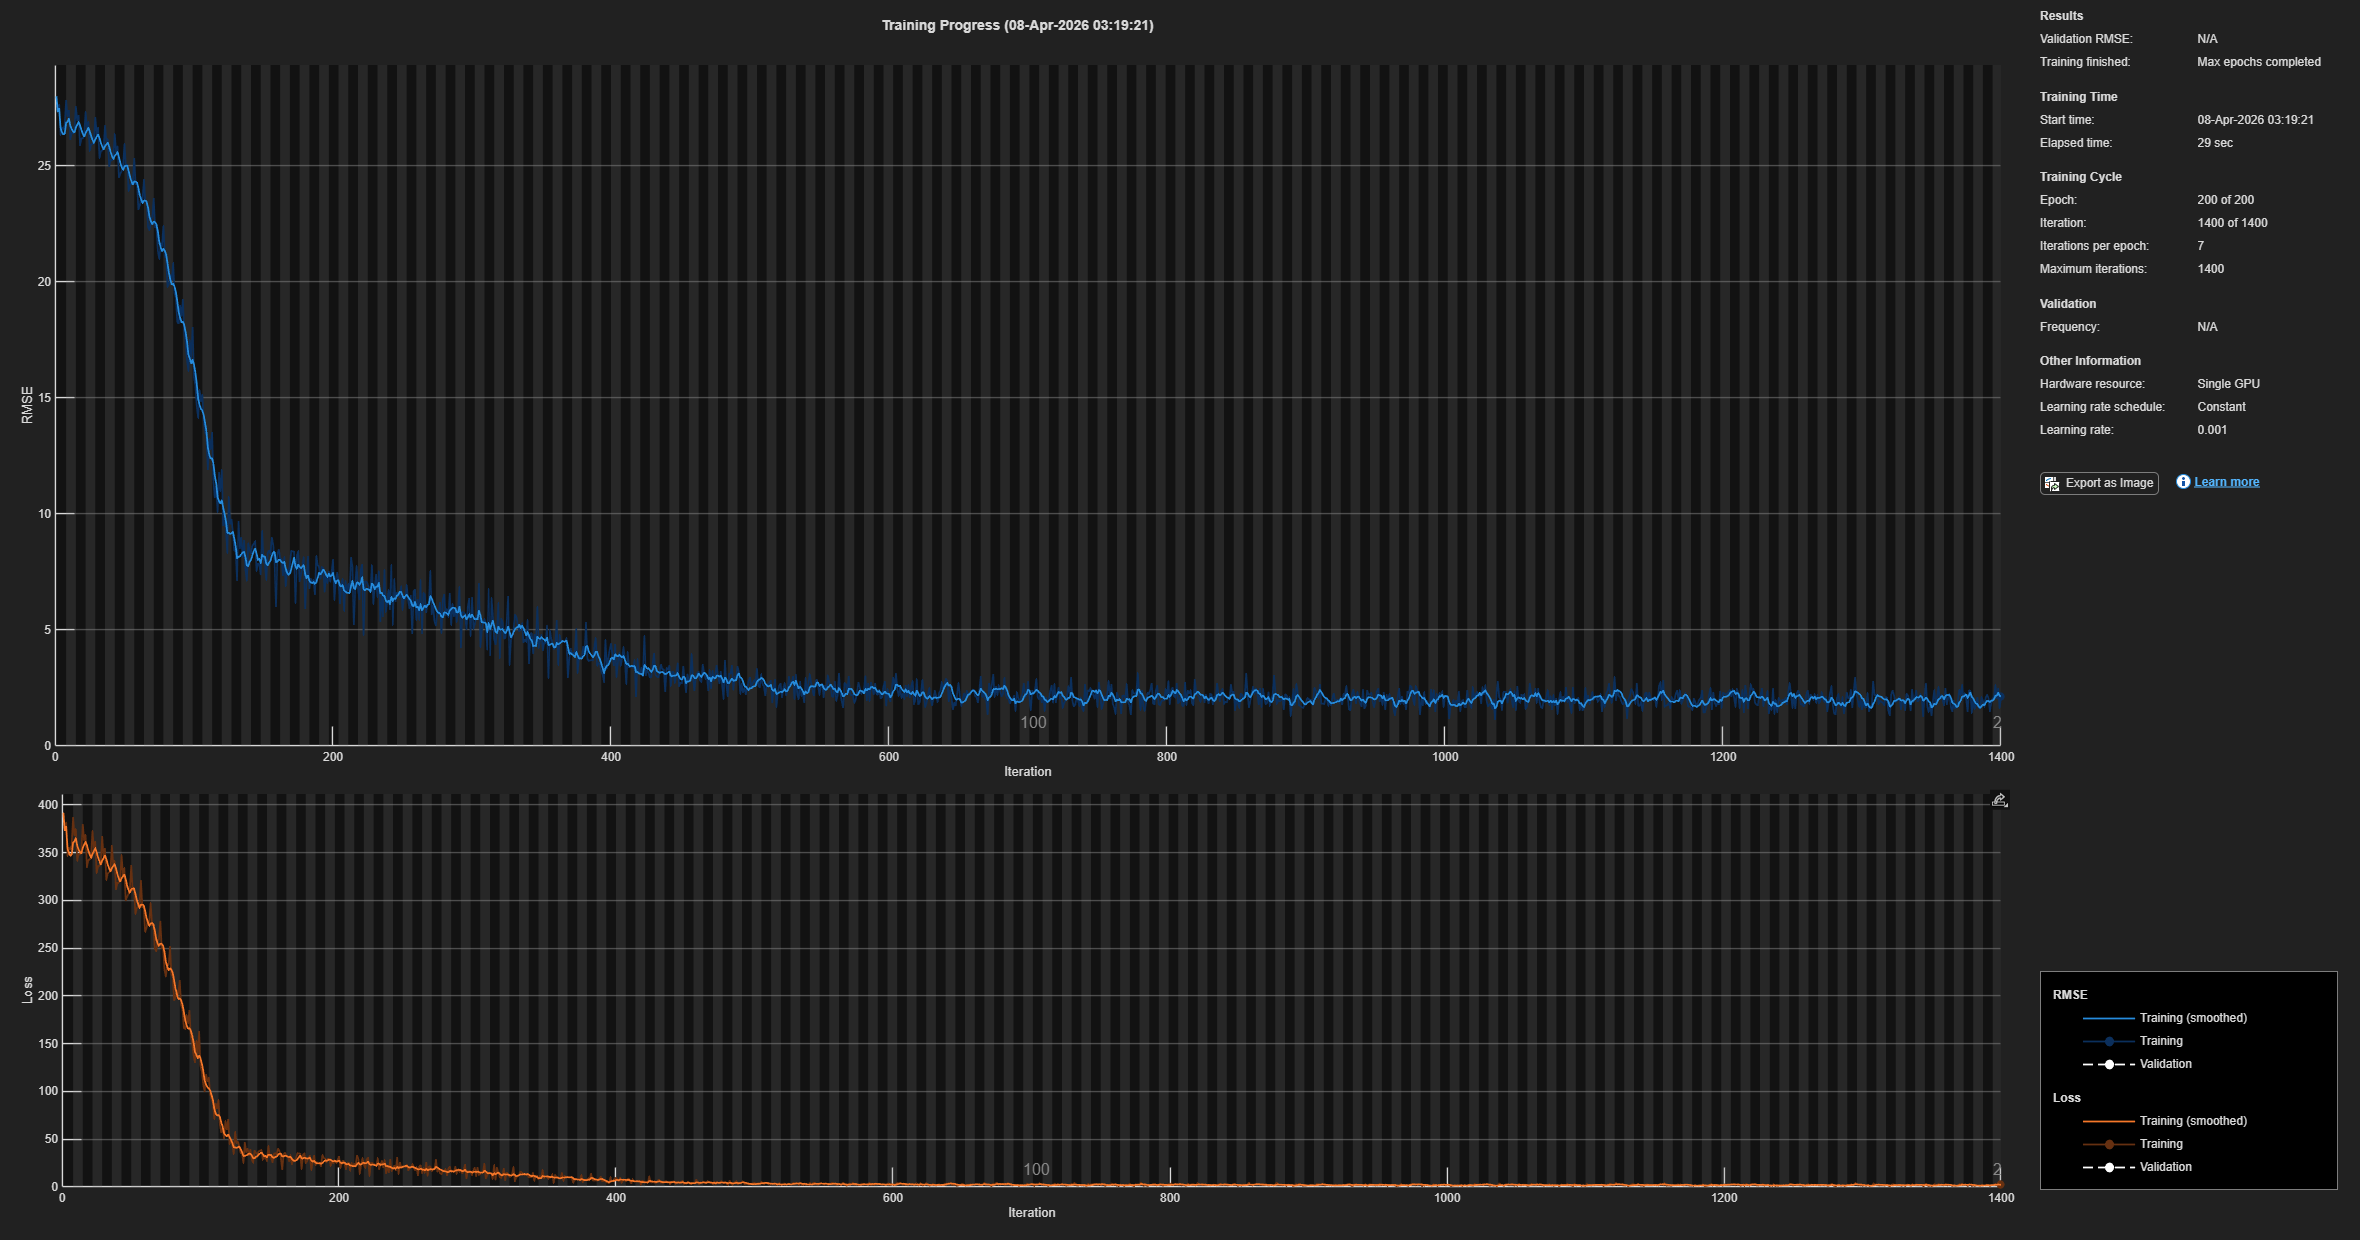


layers = [
    featureInputLayer(inputSize)
    fullyConnectedLayer(64)
    reluLayer
    dropoutLayer(0.2)
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(2)  % 2 выхода!
    regressionLayer
];

options = trainingOptions('adam', ...
    'MaxEpochs', 200, ...
    'MiniBatchSize', 16, ...
    'Plots', 'training-progress');

% ✅ trainNetwork(X, Y, layers, options) - N x features!
net = trainNetwork(X_norm, y_results, layers, options);

##  Графики результатов

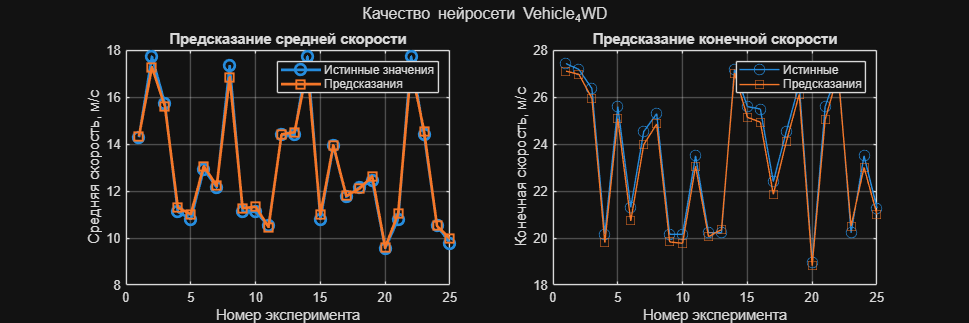

%% ✅ ВИЗУАЛИЗАЦИЯ результатов нейросети
% Разделим данные на train/test (20% тест)
N = size(X_norm,1);
test_idx = randsample(N, round(0.2*N), false);  % 20% случайных
train_idx = ~ismember(1:N, test_idx);

X_test = X_norm(test_idx, :);
ytest = y_results(test_idx, 1);  % ← Истинные v_ср!
y_test_pred = predict(net, X_test);  % Предсказания

%% ГРАФИКИ
figure('Position', [100 100 1200 400]);

% График 1: v_ср (средняя скорость)
subplot(1,2,1);
plot(ytest, 'o-', 'DisplayName', 'Истинные значения', 'MarkerSize', 8, 'LineWidth', 2);
hold on;
plot(y_test_pred(:,1), 's-', 'DisplayName', 'Предсказания', 'MarkerSize', 8, 'LineWidth', 2);
xlabel('Номер эксперимента'); ylabel('Средняя скорость, м/с');
title('Предсказание средней скорости'); legend; grid on;

% График 2: v_конец (конечная скорость)  
subplot(1,2,2);
plot(y_results(test_idx,2), 'o-', 'DisplayName', 'Истинные', 'MarkerSize', 8);
hold on;
plot(y_test_pred(:,2), 's-', 'DisplayName', 'Предсказания', 'MarkerSize', 8);
xlabel('Номер эксперимента'); ylabel('Конечная скорость, м/с');
title('Предсказание конечной скорости'); legend; grid on;

sgtitle('Качество нейросети Vehicle_4WD');

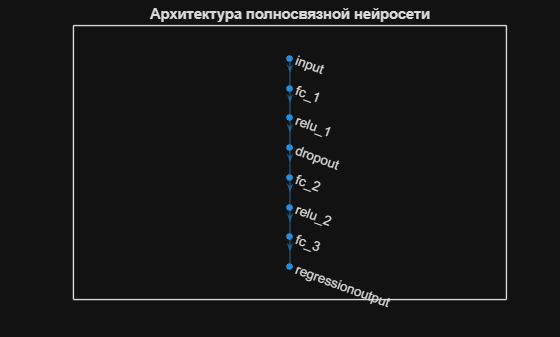


% Архитектура сети
figure
plot(net)
title('Архитектура полносвязной нейросети')

## Оценка качества

% Метрики
rmse_mean = sqrt(mean((ytest - y_test_pred(:,1)).^2));

Arrays have incompatible sizes for this operation.

Related documentation

rmse_end = sqrt(mean((y_results(test_idx,2) - y_test_pred(:,2)).^2));

fprintf('RMSE v_ср: %.3f м/с\n', rmse_mean);
fprintf('RMSE v_конец: %.3f м/с\n', rmse_end);
fprintf('R² = %.3f\n', 1 - mean((ytest - y_test_pred(:,1)).^2)/var(ytest));

analyzeNetwork(net)